% pid_design.m
% PID controller design and closed-loop response

clc;
clear;
close all;

% === PLANT (same as Section 1) ===
K = 1;
tau = 0.5;
G = tf(K, [tau 1]);

% === INITIAL PID GAINS ===
Kp = 6;
Ki = 3;
Kd = 0.1;

% Create PID controller
C = pid(Kp, Ki, Kd);

% Closed-loop system
T = feedback(C * G, 1);

% Plot response
figure;
step(T);
grid on;
title('Closed-Loop PID Response');
xlabel('Time (seconds)');
ylabel('Motor Speed');

% Get performance metrics
info = stepinfo(T);
disp('PID Step Response Info:');

PID Step Response Info:


disp(info);

         RiseTime: 0.4842
    TransientTime: 4.4342
     SettlingTime: 4.0251
      SettlingMin: 0.9000
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 15.6692



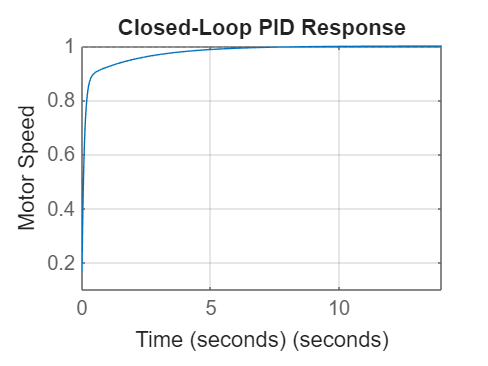


% === YOUR SAVE PATH ===
save_path = 'C:\Users\SABEE\OneDrive\Desktop\Attachments\Desktop\sabeeh\My projects\Control systems\end_eval';

% Create folder if needed
if ~exist(save_path, 'dir')
    mkdir(save_path);
end

% Save plot
saveas(gcf, fullfile(save_path, 'pid_response.png'));